# CV1 from pzr

% zaklinadla
clear vars; clc; close all;

% params
addpath('funcs'); 

data_path = 'data';
file_list_folder = 'filelists';

fileLists = {'FileList1.txt'};


Processing file list: filelists/FileList1.txt


Processing: files/DSVowels.wav


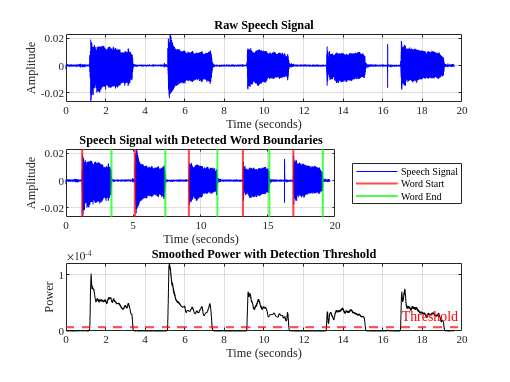


Detected words: 5
Word 1: Start = 1.20 sec, End = 3.38 sec
Word 2: Start = 5.13 sec, End = 7.38 sec
Word 3: Start = 9.14 sec, End = 11.25 sec
Word 4: Start = 13.15 sec, End = 15.12 sec
Word 5: Start = 16.90 sec, End = 19.09 sec


Processing: files/DSVowels_mine.wav


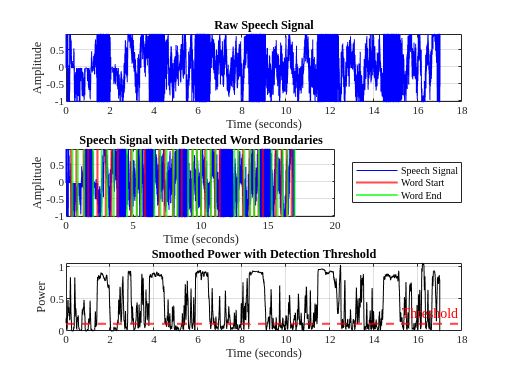


Detected words: 34
Word 1: Start = 0.37 sec, End = 0.47 sec
Word 2: Start = 0.77 sec, End = 0.87 sec
Word 3: Start = 1.32 sec, End = 1.35 sec
Word 4: Start = 1.65 sec, End = 2.02 sec
Word 5: Start = 2.34 sec, End = 2.66 sec
Word 6: Start = 2.96 sec, End = 3.07 sec
Word 7: Start = 3.37 sec, End = 3.55 sec
Word 8: Start = 3.85 sec, End = 4.53 sec
Word 9: Start = 4.83 sec, End = 4.92 sec
Word 10: Start = 5.26 sec, End = 5.26 sec
Word 11: Start = 5.56 sec, End = 5.57 sec
Word 12: Start = 5.87 sec, End = 6.56 sec
Word 13: Start = 6.93 sec, End = 7.01 sec
Word 14: Start = 7.32 sec, End = 7.47 sec
Word 15: Start = 7.95 sec, End = 7.99 sec
Word 16: Start = 8.29 sec, End = 8.30 sec
Word 17: Start = 8.60 sec, End = 9.08 sec
Word 18: Start = 9.40 sec, End = 9.43 sec
Word 19: Start = 9.73 sec, End = 9.74 sec
Word 20: Start = 10.04 sec, End = 10.05 sec
Word 21: Start = 10.35 sec, End = 10.44 sec
Word 22: Start = 10.75 sec, End = 10.76 sec
Word 23: Start = 11.08 sec, End = 11.13 sec
Word 24: Start 

Processing: files/DSVowels_mine2.wav


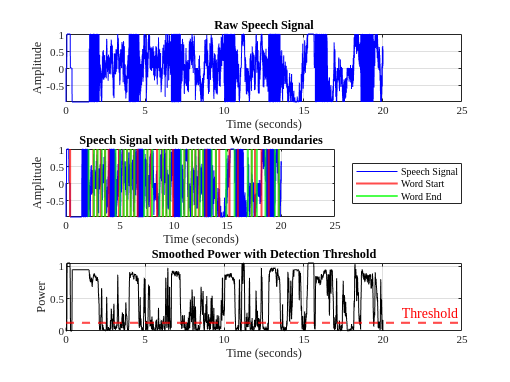


Detected words: 35
Word 1: Start = 0.38 sec, End = 2.10 sec
Word 2: Start = 2.55 sec, End = 2.60 sec
Word 3: Start = 2.90 sec, End = 2.93 sec
Word 4: Start = 3.23 sec, End = 3.32 sec
Word 5: Start = 3.62 sec, End = 3.64 sec
Word 6: Start = 3.97 sec, End = 4.61 sec
Word 7: Start = 4.91 sec, End = 5.02 sec
Word 8: Start = 5.34 sec, End = 5.37 sec
Word 9: Start = 5.67 sec, End = 5.69 sec
Word 10: Start = 6.00 sec, End = 6.02 sec
Word 11: Start = 6.32 sec, End = 6.36 sec
Word 12: Start = 6.66 sec, End = 7.26 sec
Word 13: Start = 7.57 sec, End = 7.58 sec
Word 14: Start = 7.88 sec, End = 8.00 sec
Word 15: Start = 8.47 sec, End = 8.69 sec
Word 16: Start = 8.99 sec, End = 9.01 sec
Word 17: Start = 9.32 sec, End = 9.35 sec
Word 18: Start = 9.65 sec, End = 9.65 sec
Word 19: Start = 9.95 sec, End = 10.70 sec
Word 20: Start = 11.00 sec, End = 11.00 sec
Word 21: Start = 11.37 sec, End = 11.39 sec
Word 22: Start = 11.70 sec, End = 11.71 sec
Word 23: Start = 12.01 sec, End = 12.05 sec
Word 24: Start

Processing: files/DSVowels_mine4.wav


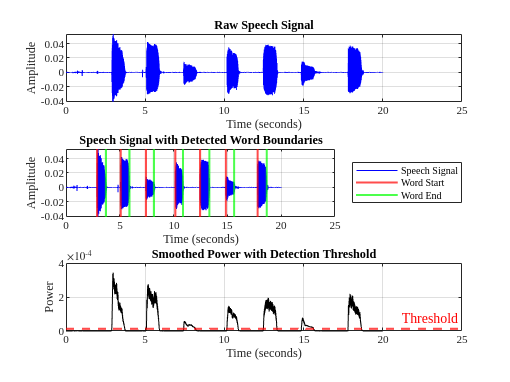


Detected words: 7
Word 1: Start = 2.89 sec, End = 3.71 sec
Word 2: Start = 5.08 sec, End = 5.89 sec
Word 3: Start = 7.43 sec, End = 8.17 sec
Word 4: Start = 10.16 sec, End = 10.87 sec
Word 5: Start = 12.46 sec, End = 13.33 sec
Word 6: Start = 14.86 sec, End = 15.62 sec
Word 7: Start = 17.81 sec, End = 18.66 sec


% Loop through each file list
for i = 1:length(fileLists)
    % Construct full path to the file list
    fileListPath = fullfile(file_list_folder, fileLists{i});
    
    disp(['Processing file list: ', fileListPath]);

    if exist(fileListPath, 'file')
        % Open and read the file list
        fileID = fopen(fileListPath, 'r');
        fileNames = textscan(fileID, '%s'); % Read all lines as strings
        fclose(fileID);
        
        % Convert to a cell array of strings
        fileNames = fileNames{1};
        
        % Process each file in the list
        for j = 1:length(fileNames)
            % Construct full path to the audio file
            audioFilePath = fullfile(fileN`ames{j});
            
            % Check if the audio file exists
            if exist(audioFilePath, 'file')
                disp(['Processing: ', audioFilePath]);
                
                % Run detection on an audio file (20s speech with pauses)
                [words, starts, ends] = xtractWords(audioFilePath, 1000);

                
                if ~isempty(words)
                    
                   % bruh

                else
                    disp('No word detected, skipping spectral feature extraction.');
                end
                
            else
                disp(['File not found: ', audioFilePath]);
            end
        end
    else
        disp(['File list not found: ', fileListPath]);
    end
end